clear,clc
%Defining m1(t)
%Looks like a sawtooth funciton so will define it as such (Ziad) 

%Time Period (s)
m1TimePeriod = 1e-3;
m1_EndTime = 1;
m1divisions = 100000;

m1timeAxis = linspace(0,m1_EndTime,m1divisions);
m1TimeShift = 0.5e-3

m1TimeShift = 5.0000e-04

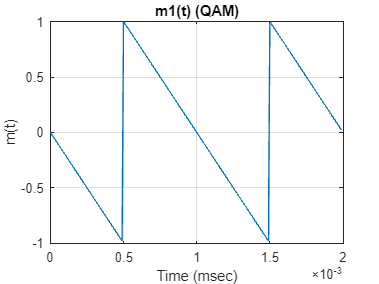


m1TimeShiftedVector = m1timeAxis - m1TimeShift; 

m1 = sawtooth(2*pi*(1/m1TimePeriod)*m1TimeShiftedVector,0);

%Plotting m2

%This is called logical indexing, will itterate to this condition
m1T_cutoff = 2e-3;
%mask is passed into the index
mask = m1timeAxis <= m1T_cutoff;

figure
plot(m1timeAxis(mask),m1(mask));
title('m1(t) (QAM)')
xlabel('Time (msec)');
ylabel('m(t)');
grid on 
xticks(linspace(0,m1T_cutoff,5));


%Generation of m1(t) complete 
%----------------------------------------

%Definig m2(t)
m2TimeRun = 6e-3;
m2TimePeriod = 2e-3;

%number of switches per time period
m2NumberSteps = 4;

%Defines how many times a switch will from on discrete value to another 
%based on the total time we expect generate m2 for
m2NumberofSwitches = round((m2TimeRun/m2TimePeriod)*m2NumberSteps);

m2MaxAmp = 1;

m2Elements = zeros(1,m2NumberofSwitches);
m2ValueElement = [0,0.5,1.5,2];


%This is the time period where the signal is constant before a switch
m2TimeSectionPeriod = m2TimePeriod/4;

%This chooses the amount of points we want to generate perswitch
m2PointEvery = 1e-6;
m2pointsPerSection = round(m2TimeSectionPeriod/m2PointEvery)

m2pointsPerSection = 500


%Generate each element for each switch
for n = 1:m2NumberofSwitches 
  m2Elements(n) = m2MaxAmp - m2ValueElement(mod(n-1,m2NumberSteps)+1);
end

%This vector describes m2 by repeating each point per swtich a certain
%number of times 
m2Complete = repelem(m2Elements,m2pointsPerSection)

m2Complete =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1




%Plottin m2
t_m2 = linspace(0,m2TimeRun,((m2TimeRun)/(m2TimePeriod))*m2NumberSteps*m2pointsPerSection)

t_m2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


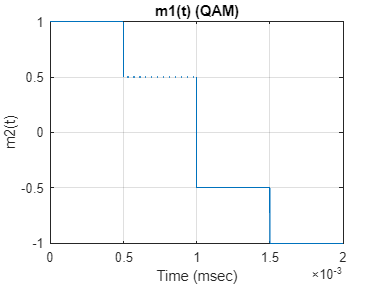


m2T_cutoff = 2e-3;
m2Mask = t_m2 <= m2T_cutoff;

figure
plot(t_m2(m2Mask),m2Complete(m2Mask));
title('m1(t) (QAM)')
xlabel('Time (msec)');
ylabel('m2(t)');
grid on 


%Generation of m2(t) complete 
%----------------------------------------
